clear

addpath('matlab_functions\')

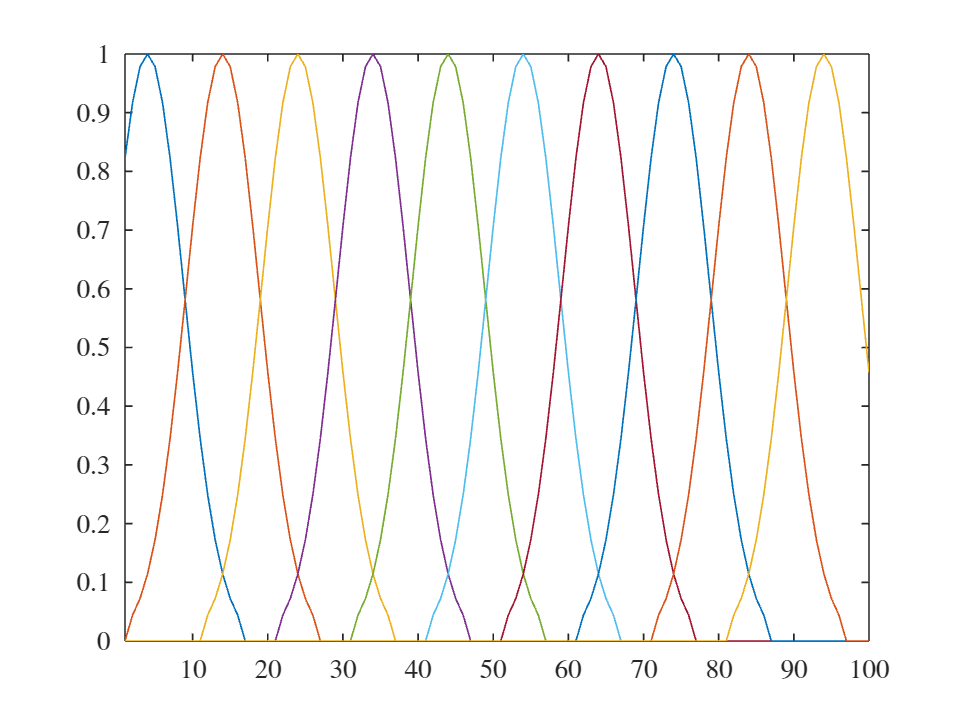

N = 100; % number of elements
M = 10;  % number of observations

Phi = buildDictionary(N, M, 25);
Phi = full(Phi);

figure
plot(Phi.')
xlim([1 N])


x = zeros(N,1);
x(10:15) = 1;
x(50:57) = 1;
x(70:72) = 1;

y = Phi * x + randn(M,1) * 0;

tic
x2 = BBL(Phi, y, 'Method','BetaPrior', 'a',0.3, 'b',0.3, 'MaxIterations',100);
% x2 = BBL(Phi, y, 'Method','WeightedPrior', 'Sparsity',0.5, 'MaxIterations',100);
toc

Elapsed time is 0.056487 seconds.


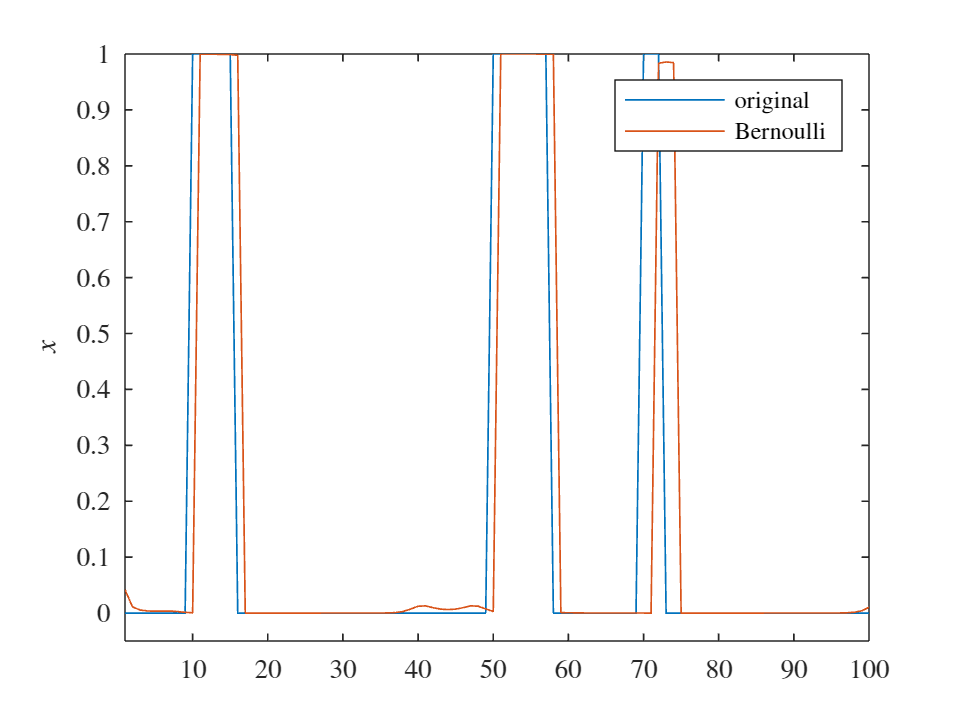


figure
hold on
plot(x,  'DisplayName','original')
plot(x2, 'DisplayName','Bernoulli')
legend('Interpreter','latex')
xlim([1 N])
ylim([-0.05 inf])
ylabel('$x$', 'Interpreter','latex')
box on

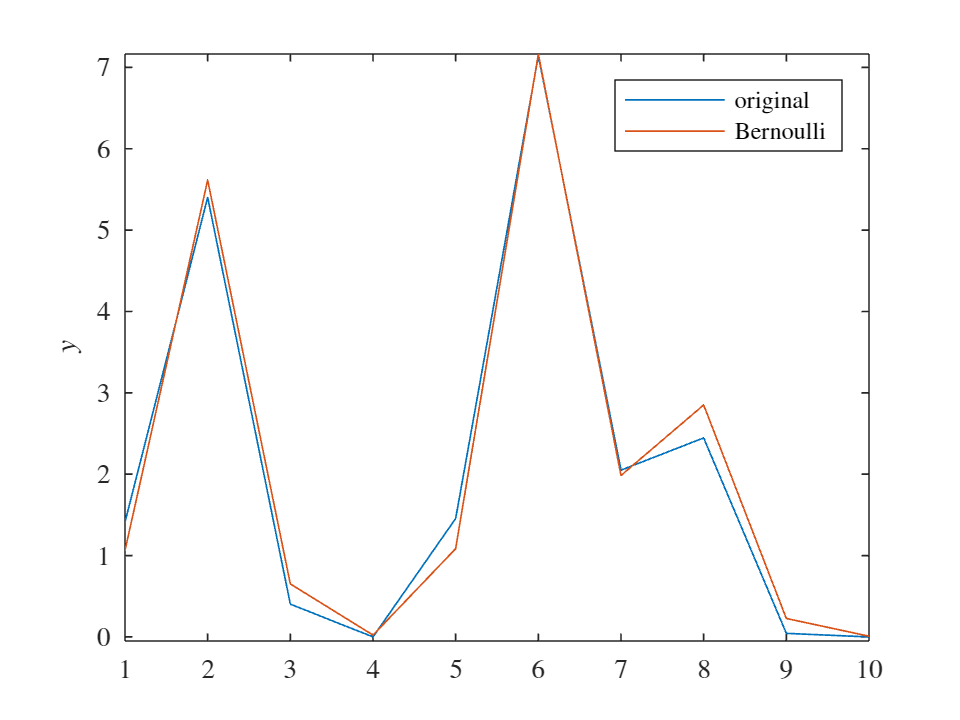


figure
hold on
plot(y,        'DisplayName','original')
plot(Phi * x2, 'DisplayName','Bernoulli')
legend('Interpreter','latex')
ylim([-0.05 inf])
xlim([1 M])
ylabel('$y$', 'Interpreter','latex')
box on

clear

addpath("matlab_functions\")

Phi = [2 1 1 4];
y = 2.1;

x = BBL(Phi, y, 'Method','BetaPrior', 'a',0.3, 'b',0.4, 'MaxIterations',100);
% x = BBL(Phi, y, 'Method','WeightedPrior', 'Sparsity',0.4, 'MaxIterations',100);

x(x < 1e-10) = 0;

function Phi = buildDictionary(N, M, window_length)

g = gausswin(window_length);
Phi = sparse(N,M);
for j = 1:M
    a = N / (2*M) * (2*j-1) - length(g) / 2;
    a = floor(a);
    b = a + length(g) - 1;
    if a < 1
        Phi(1:b, j) = g(-a+2:end);
    elseif b > N
        Phi(a:N, j) = g(1:end+N-b);
    else
        Phi(a:b, j) = g;
    end
end
Phi = Phi.';

end